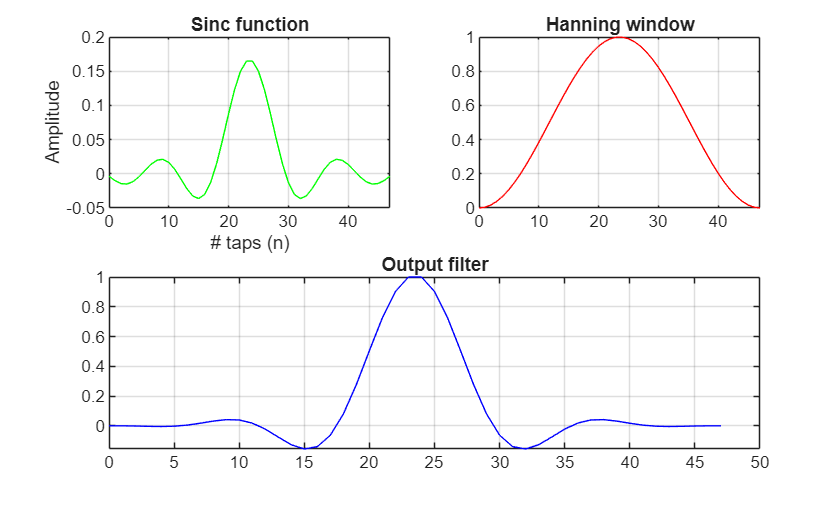

clear all; clc;
%% Filter Design
% Parameters
Nbranches = 4; % Number of branches in the polyphase filter
Ntaps = 12; % Number of taps per filter branch
N = Nbranches*Ntaps; % Total number of taps = 40
Tsample = 1; % Sampling time
BP = 1/Tsample; % Bandwidth
chann_w = BP/Ntaps; % Channel width for each branch
n = 0:N-1;
center = n - (N-1)/2; % Centers filter coefficients

% Sinc Function
sinc_function = zeros(1, N);
for i = 1:N
    if center(i) == 0
        sinc_function(i) = 2*chann_w;
    else
        sinc_function(i) = sin(2*pi*chann_w*center(i)) / (pi*center(i));
    end
end

% Generate Hanning Window
hann = 0.5 - 0.5*cos(2*pi*n/(N-1));

% Create Final Filter and Normalize
filter = sinc_function .* hann;
normal_filter = filter/max(filter(:));

% Display Filter Design
figure;
subplot(2,2,1);
plot(n, sinc_function, 'g');
grid on;
title('Sinc function');
xlabel('# taps (n)');
ylabel('Amplitude');

subplot(2,2,2)
plot(n, hann, 'r');
title('Hanning window');
grid on;

subplot(2,2,[3,4])
plot(n, normal_filter, 'b');
title('Output filter')
grid on;

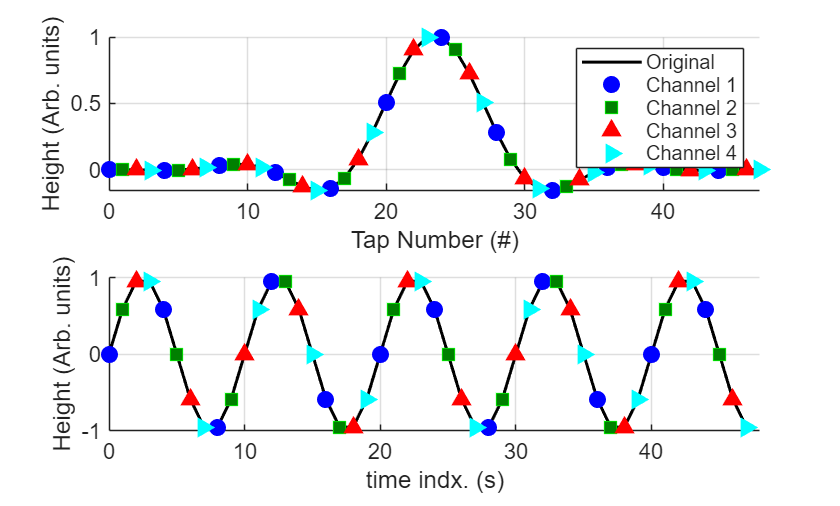


% Create input signal with same length as filter
t = 0:1:N-1;
f1 = 0.1;
input_signal = sin(2*pi*f1*t);

%% Sine
% Extract channels - each channel gets every 4th sample starting at different offsets
channel0 = input_signal(1:Nbranches:end); % Samples 1, 5, 9, 13, ...
channel1 = input_signal(2:Nbranches:end); % Samples 2, 6, 10, 14, ...
channel2 = input_signal(3:Nbranches:end); % Samples 3, 7, 11, 15, ...
channel3 = input_signal(4:Nbranches:end); % Samples 4, 8, 12, 16, ...

%% Filter
% Extract channels - each channel gets every 4th sample starting at different offsets
chann0 = normal_filter(1:Nbranches:end); % Samples 1, 5, 9, 13, ...
chann1 = normal_filter(2:Nbranches:end); % Samples 2, 6, 10, 14, ...
chann2 = normal_filter(3:Nbranches:end); % Samples 3, 7, 11, 15, ...
chann3 = normal_filter(4:Nbranches:end); % Samples 4, 8, 12, 16, ...

%% Create the polyphase filter response plot
figure;
subplot(2,1,2)
hold on;
% Plot each channel at its corresponding tap positions
plot(t, input_signal, 'Color', 'k', 'LineWidth', 1.5)
plot(0:Nbranches:N-1, channel0, 'o', 'Color', 'b', 'MarkerFaceColor', 'b', 'MarkerSize', 8);
plot(1:Nbranches:N-1, channel1, 's', 'Color', 'g', 'MarkerFaceColor', [0, 0.5, 0], 'MarkerSize', 8);
plot(2:Nbranches:N-1, channel2, '^', 'Color', 'r', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
plot(3:Nbranches:N-1, channel3, '>', 'Color', 'c', 'MarkerFaceColor', 'c', 'MarkerSize', 8);
hold off;
% Customize axes
xlabel('time indx. (s)')
ylabel('Height (Arb. units)', 'FontSize', 14)
xlim([0, length(t)]);
set(gca, 'FontSize', 11);
grid on;

% Plot filter channels
subplot(2,1,1)
hold on;
plot(0:N-1, normal_filter, 'Color', 'k', 'LineWidth', 1.5)
plot(0:Nbranches:N-1, chann0, 'o', 'Color', 'b', 'MarkerFaceColor', 'b', 'MarkerSize', 8);
plot(1:Nbranches:N-1, chann1, 's', 'Color', 'g', 'MarkerFaceColor', [0, 0.5, 0], 'MarkerSize', 8);
plot(2:Nbranches:N-1, chann2, '^', 'Color', 'r', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
plot(3:Nbranches:N-1, chann3, '>', 'Color', 'c', 'MarkerFaceColor', 'c', 'MarkerSize', 8);
hold off;
% Customize axes
xlabel('Tap Number (#)', 'FontSize', 14);
ylabel('Height (Arb. units)', 'FontSize', 14)
xlim([0, N-1]);
set(gca, 'FontSize', 11);
grid on;

% Add legend
legend('Original', 'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4', 'Location', 'northeast', 'FontSize', 10);